## Declare Variables

% Constant variables
altitude = 25000; % Desired altitude of 25000 m
payloadMass = 500; % Desired payload mass of 500 kg
FS = [1:.5:5]'; % Self-selected number in range 1:5
Pgage = 10; % Gage pressure in Pa
gravity = 9.81; % Acceleration of gravity in m / s^2

% Variable variables (o_o )
    % Measurements based on information found in:
    % http://www.matweb.com/search/datasheet_print.aspx?matguid=bcd1ad1e1a7445aca5321d26f00bdf12
materialThickness = 3.81 * 10^-5; % Balloon material thickness in m
YS = 15.5 * 10^6; % Yield strength of balloon material in Pa
materialDensity = 924; % Density of material in kg / m^3
gasConstHe = 8.31e3 % Gas constant for Helium in kJ / kg*K

% Create table for data
data = table(FS, 'VariableNames', {'FactorSafety'})

## Declare equations

% Calculate sphere volume given radius
sphereVol = @(r) (4/3) * pi * (r.^3)

% Calculate yield strength given factor of safety, gage pressure, radius,
% and thickness
yieldStrength = @(F_S, Pgage, r, t) (F_S .* (Pgage * r)) ./ (2 * t)

% Calculate stress given gage pressure, radius, and thickness
stress = @(Pgage, r, t) (Pgage * r) / (2 * t)

% Calculate radius given density of air, pressure of air, factor of safety,
% yield strength of material, and temperature
radius = @(denAir, pressureAir, FS, YS, temp) abs(payloadMass ./ ( ((4/3) .* denAir .* pi) - (((materialDensity .* 2 .* pi .* Pgage) .* FS) ./ YS) - ( ((pressureAir .* 4 .* pi) / (3 .* gasConstHe .* temp))) )) .^ (1/3)

% Calculate buoyancy force given fluid density, gravity, and volume
buoyancy = @(density, volume) density * gravity * volume

% Calculate force of gravity given mass
weight = @(mass) mass * gravity

thick = @(FS, radius) (FS .* Pgage .* radius) ./ (2 .* YS);

## Calculate approximate balloon radius

bisonTopSpeed = 35 * 0.44704 % m/s

## Begin calculations

% Find atmospheric conditions based on 1976 model
[temp, speedSound, pressure, densityAir] = atmoscoesa(altitude)

% Find radius of balloon 
data.balloonRadius = radius(densityAir, pressure, data.FactorSafety, YS, temp); % Radius in m

% Find volume of balloon
data.balloonVolume = sphereVol(data.balloonRadius); % Volume in m^3

% Find buoyancy force
data.forceBuoyancy = buoyancy(densityAir, data.balloonVolume); % Buoyancy force in N

% Find force of gravity (weight of balloon)
data.thickness = thick(data.FactorSafety, data.balloonRadius);
data.amtBalloonMaterial = data.balloonVolume - sphereVol(data.balloonRadius - data.thickness); % m^3
data.massHeFBE = (densityAir * data.balloonVolume) - payloadMass - (materialDensity * data.amtBalloonMaterial); % Mass of He in kg
data.totalMass = (data.amtBalloonMaterial * materialDensity) + payloadMass + data.massHeFBE; % Total mass of the system in kg
data.forceGravity = weight(data.totalMass); % Force of gravity of the system in N --> should be equal to the force of buoyancy

% Find mass of He from PV=nRT equation
data.massHePVNRT = (pressure .* data.balloonVolume) ./ (gasConstHe * temp);

data

## Find effects of temperature change

% Given values
alpha_sb = 0.6;
epsilon_b = 0.8;
alpha_eb = epsilon_b;
q_sun = 1353; % W / m^2
q_earth = 237; % W / m^2

Q_dot_solar = (alpha_sb * q_sun * pi) .* (data.balloonRadius .^ 2) % Change in thermal energy of the sun in W
Q_dot_earth = (alpha_eb * q_earth * pi) .* (data.balloonRadius .^ 2) % Change in thermal energy of the earth in W

## Graphs of features vs Factor of Safety

gasConstHe = 8310

data = 9×1 table
    FactorSafety
    ____________

          1     
        1.5     
          2     
        2.5     
          3     
        3.5     
          4     
        4.5     
          5     


sphereVol = function_handle with value:
    @(r)(4/3)*pi*(r.^3)


yieldStrength = function_handle with value:
    @(F_S,Pgage,r,t)(F_S.*(Pgage*r))./(2*t)


stress = function_handle with value:
    @(Pgage,r,t)(Pgage*r)/(2*t)


radius = function_handle with value:
    @(denAir,pressureAir,FS,YS,temp)abs(payloadMass./(((4/3).*denAir.*pi)-(((materialDensity.*2.*pi.*Pgage).*FS)./YS)-(((pressureAir.*4.*pi)/(3.*gasConstHe.*temp))))).^(1/3)


buoyancy = function_handle with value:
    @(density,volume)density*gravity*volume


weight = function_handle with value:
    @(mass)mass*gravity


bisonTopSpeed = 15.6464

temp = 221.6500

speedSound = 298.4551

pressure = 2.5110e+03

densityAir = 0.0395

data = 9×9 table
    FactorSafety    balloonRadius    balloonVolume    forceBuoyancy    amtBalloonMaterial    massHeFBE    totalMass    forceGravity    massHePVNRT
    ____________    _____________    _____________    _____________    __________________    _________    _________    ____________    ___________

          1            14.748            13438           5202.6             0.10414           -65.892      530.34         5202.6         18.319   
        1.5            14.808            13601           5265.9             0.10499           -60.221      536.79         5265.9         18.542   
          2            14.869            13769           5330.7             0.10585     

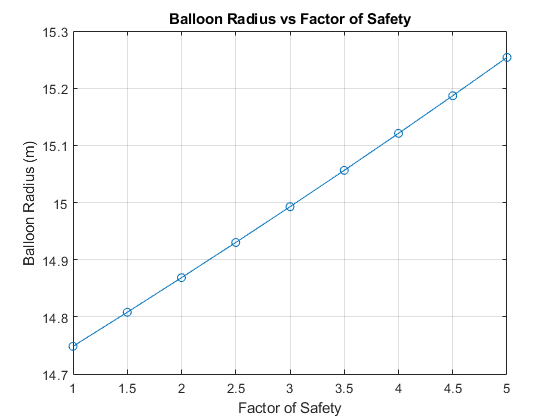

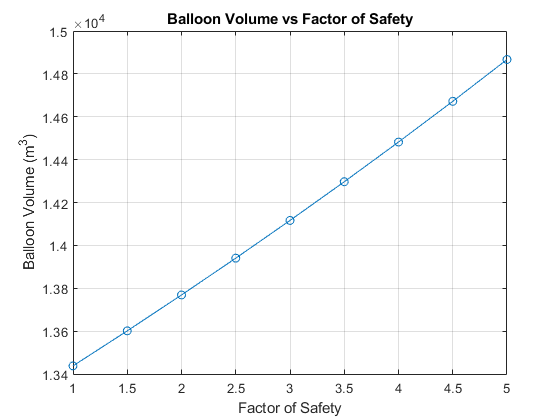

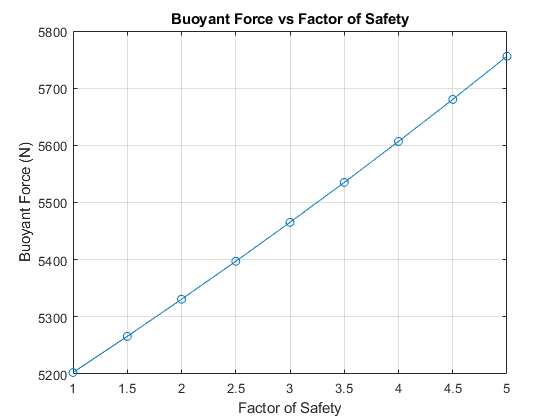

plot(data.FactorSafety, data.balloonRadius, 'o-')
grid on
title("Balloon Radius vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Radius (m)")

plot(data.FactorSafety, data.balloonVolume, 'o-')
grid on
title("Balloon Volume vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Volume (m^3)")

plot(data.FactorSafety, data.forceBuoyancy, 'o-')
grid on
title("Buoyant Force vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Buoyant Force (N)")